clc;clear;warning off;close all;
a=0.871;

A.

a. 

Układ stabilny

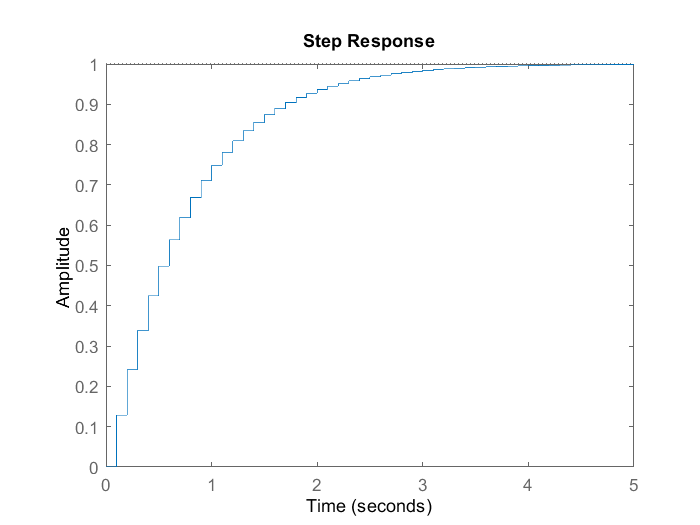

z=tf('z',0.1);
P=(1-a)/(z-a);
step(P)

b.

syms P(z) p(n) T(z) t(n)
P(z)=(1-a)/(z-a);
T(z)=P(z)/(P(z)+1);

k_UO=P(1)

$$k\_UO = 1$$

k_UZ=T(1)

$$k\_UZ = \frac{1}{2}$$


p(z)=iztrans(P);
t(n)=iztrans(T);



c. 

Układ jest raczej wolny

d.

 wykres odpowiedzi jednostkowej u(k)=1(k) -> U(z)=z/(z-1)

z=tf('z',0.1);
P=(1-a)/(z-a)

P =
 
    0.129
  ---------
  z - 0.871
 
Sample time: 0.1 seconds
Discrete-time transfer function.



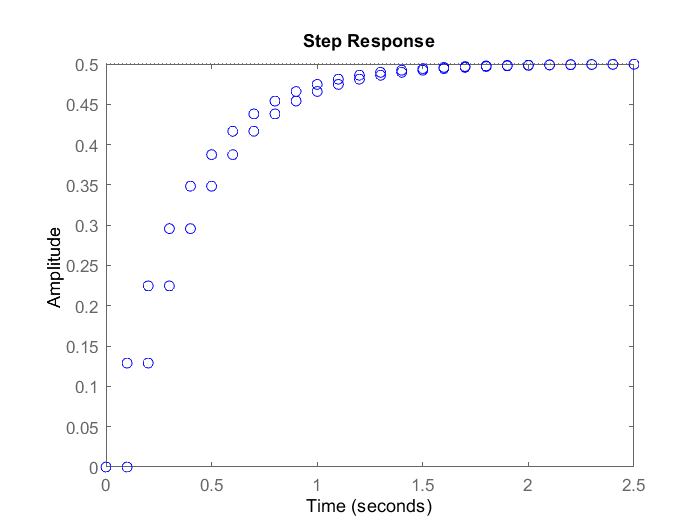

figure
step(feedback(P,1),"o")

[h,t]=step(feedback(P,1));
n = t(h>=0.9*0.5);

Odpowiedz:

n(1)

ans = 0.8000

B.

z=tf('z',0.1);

P(z)

B=1-a;
A=z-a;
P=B/A;

T(z)

p=0.7;
L=1-p;
M=z-p;
T=L/M

T =
 
    0.3
  -------
  z - 0.7
 
Sample time: 0.1 seconds
Discrete-time transfer function.



C(z)

S=L/B;
R=(M-S*B)/A;
C=S/R

C =
 
  2.326 z - 2.026
  ---------------
       z - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.



G0(z)

G0=C*P

G0 =
 
     0.3 z - 0.2613
  ---------------------
  z^2 - 1.871 z + 0.871
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Sprawdzenie, czy C(z) jest poprawnie obliczone

zpk(minreal(feedback(G0,1)))

ans =
 
    0.3
  -------
  (z-0.7)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



[num,den]=tfdata(feedback(G0,1),'v');
roots(num);
roots(den);

a.

 Nie

b. 

Tak

c.

- S(s)=E(s)/R(s)

S=zpk(minreal(feedback(1,C*P)))

S =
 
   (z-1)
  -------
  (z-0.7)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



- U(s)/R(s)

zpk(minreal(feedback(C,P)))

ans =
 
  2.3256 (z-0.871)
  ----------------
      (z-0.7)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



- Z_D(s)=Y(s)/D(s)

- Wolny biegun nie został usunięty

Z_D=zpk(minreal(feedback(P,C)))

Z_D =
 
     0.129 (z-1)
  -----------------
  (z-0.871) (z-0.7)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



- Z_N(s)=Y(s)/N(s)

Z_N=zpk(minreal(feedback(C,P)))

Z_N =
 
  2.3256 (z-0.871)
  ----------------
      (z-0.7)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



d. 

Im większe p, tym wolniej ustala się odpowiedź jednostkowa. Maksymalna wartość sterowania pozostaje bez zmian.

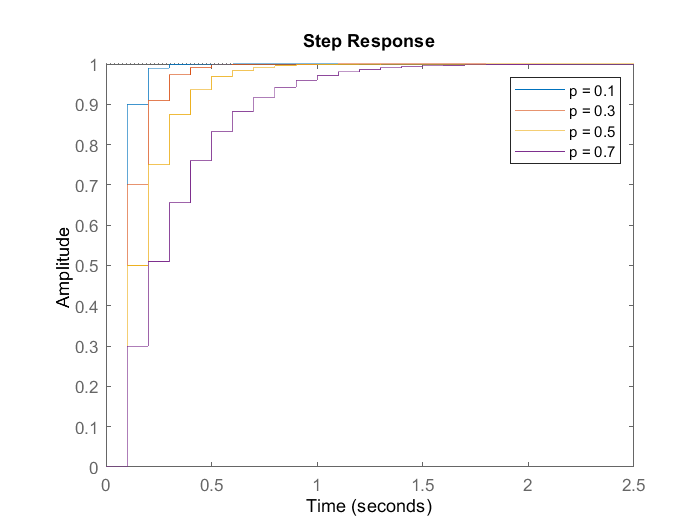

for p=0.1:0.2:0.7
  L=1-p;M=z-p;T=L/M;step(T);hold on;
end
legend('p = 0.1','p = 0.3','p = 0.5','p = 0.7')
hold off;

e. 

dla p=0

Odpowiedz jednostkowa T(s) dla p=0 ma nieskończoną wartość ustaloną.

Odpowiedź jednostkowa Z_D(s) najperw rośnie do pewnej wartości a później maleje do zera.

p=0;
L=1-p;
M=z-p;
T=L/M

T =
 
  1
  -
  z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



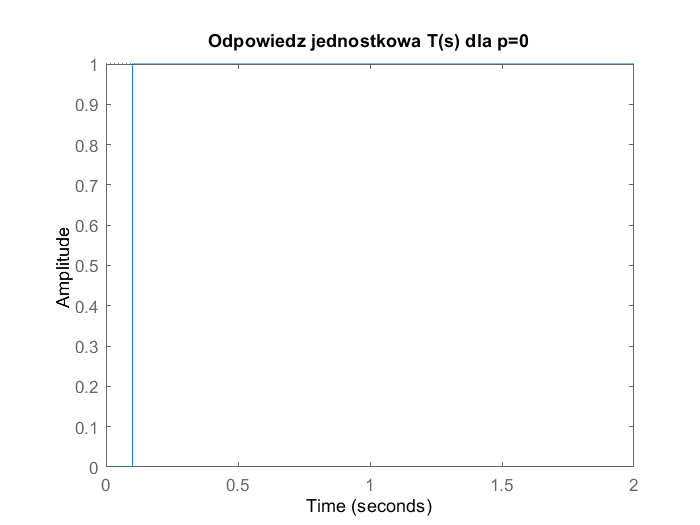

step(T)
title("Odpowiedz jednostkowa T(s) dla p=0")

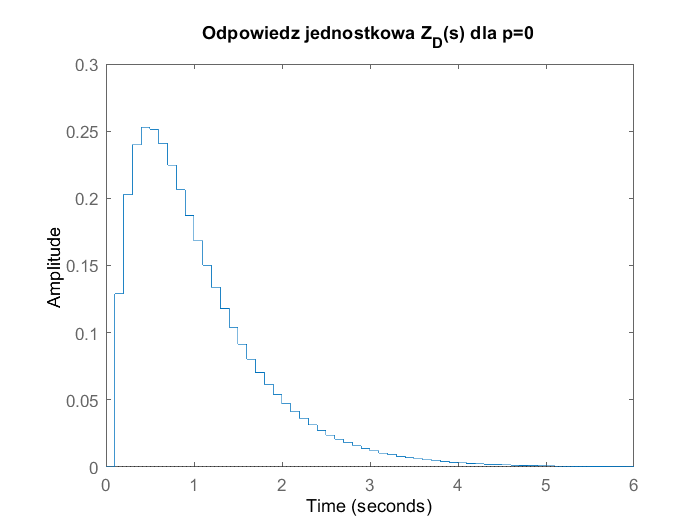

step(Z_D)
title("Odpowiedz jednostkowa Z_D(s) dla p=0")

f.

Układ T(s) osiąga większe wartości modułu transmitancji widmowej niż P(s)

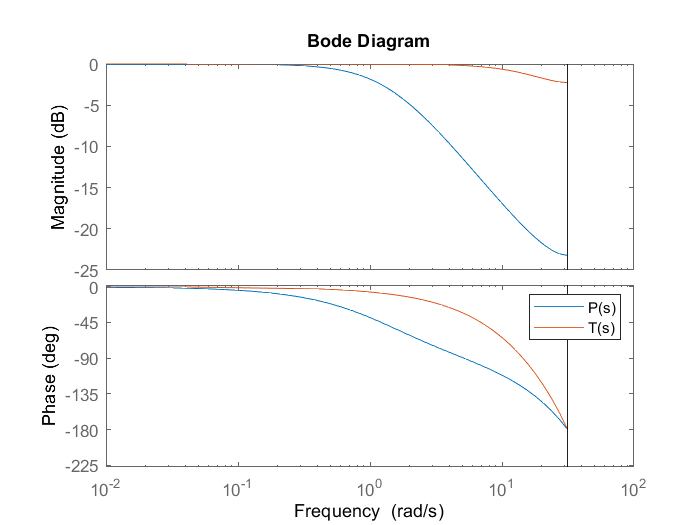

z=tf('z',0.1);
B=1-a;
A=z-a;
P=B/A;
p=1-a;
L=1-p;
M=z-p;
T=L/M;
bode(P)
hold on;
bode(T)
legend('P(s)','T(s)')
hold off

g.

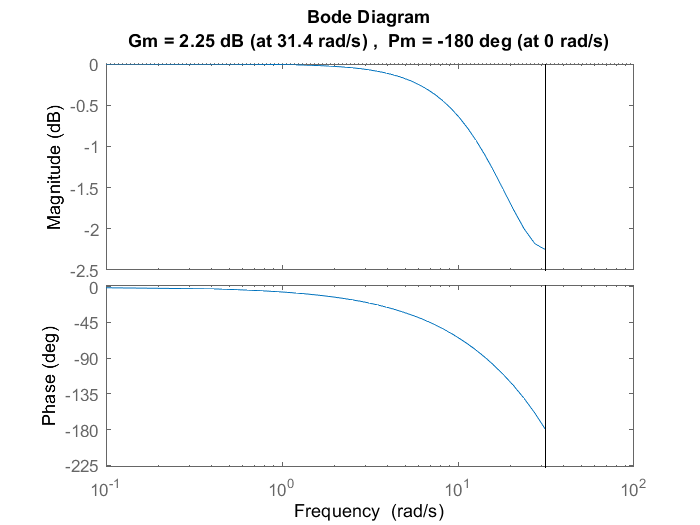

z=tf('z',0.1);
p=1-a;
L=1-p;
M=z-p;
T=L/M;
margin(T)

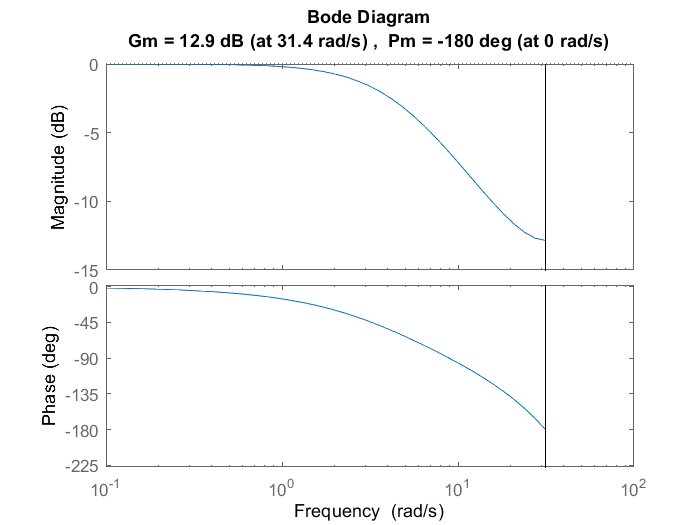

p=1-a+0.5;
L=1-p;
M=z-p;
T=L/M;
margin(T)